close all; clear; clc;

# SSv4- attempted flight profile 

**file name**: SSv4_TM15d.mlx

**keywords:** Custom Steps Sequence v4, flight profile

**date of test:** 20180715

**file created by:** 20180716, Edmonds

**last updated on:** 20180716

**primary purpose:** {Enter the primary purpose and primary input and output variables.}

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** [C_T], [C_P], [C_Q]

**Notes:**  Forgot to measure air density. Using today's air density (0.00228603631 slugs/ft^3) for all of the data collected on 20180715. 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.00228603631;                  %[slugs/ft^3]

% Motor Specs
radius = 7.5/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('SSv4_TM15d.mat');
time = SSv4_TM15d(:,1);                       % [sec]
PWM = SSv4_TM15d(:,2);                        % [micro sec]
Q = SSv4_TM15d(:,4);                          % [ft.lbf]
T = SSv4_TM15d(:,5);                          % [lbf]
Input_V = SSv4_TM15d(:,6);                    % [Volts]
Input_A = SSv4_TM15d(:,7);                    % [Amps]
rot_speed_rad = SSv4_TM15d(:,8);              % [rad/sec]
% convert to RPM for plotting purposes
rot_speed_rpm = rot_speed_rad ./ (pi/30);   % [RPM]
P_in_W = SSv4_TM15d(:,9);                     % [Watts]
P_out_W = SSv4_TM15d(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out = P_out_W .* 0.7478;                  % [ft.lbf/sec]         
P_in = P_in_W .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff = SSv4_TM15d(:,11);                 % [%]
Prop_Eff = SSv4_TM15d(:,12);                  % [lbf/Watts]
Overall_Eff = SSv4_TM15d(:,13);               % [lbf/Watts]  
Motor_Temp = SSv4_TM15d(:,14);                % [F]


Convert the following lines to code if this is for the 90% settling time test. Delete if not applicable.

*        Note: The empty column labeled "App Messages" must have been deleted for this part to be correct.*

Settling_time = Percent_inc10(:,16); % [s]

Max_Acc = Percent_inc10(:,17);      % [RPM]

## Thrust, Power, and Torque Coefficents

C_T = T ./ (p .* area * (rot_speed_rad * radius).^2);
C_P = P_out ./ (p .* area .* (rot_speed_rad .* radius).^3);
C_Q = Q ./ (p .* area .* (rot_speed_rad .* radius).^(2) .* radius);

## Plots

The following are standard charts. Remove, add, and edit as needed.

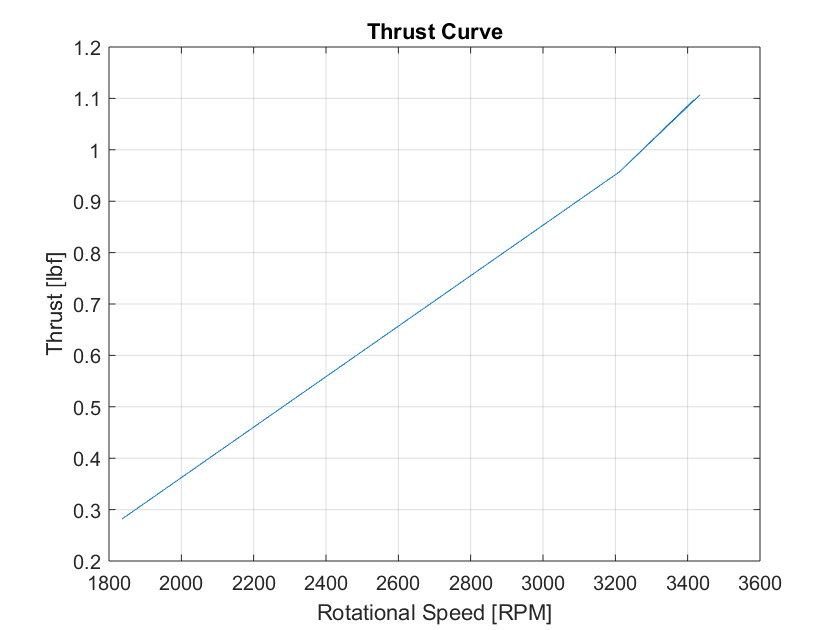

figure(1)
plot(rot_speed_rpm, T); title('Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

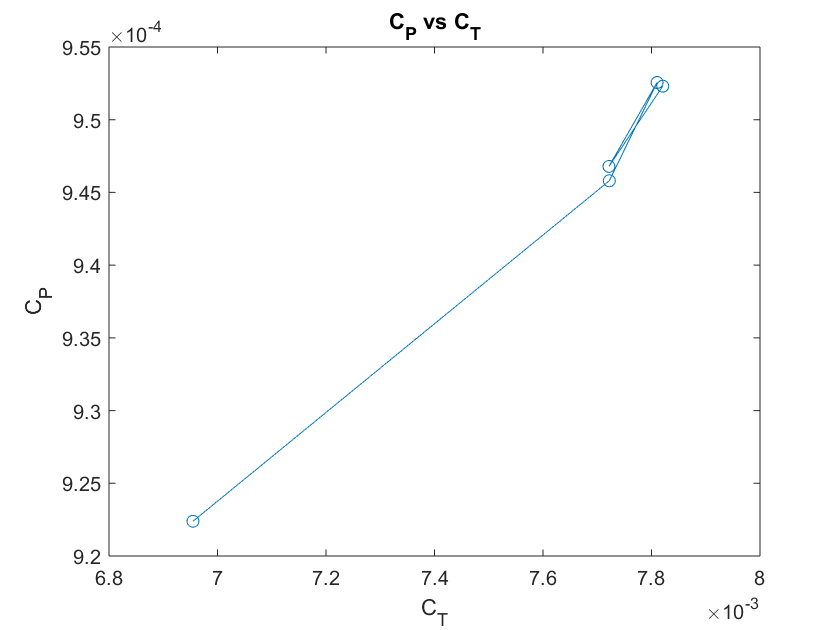


figure(2)
plot(C_T, C_P,'o-');
title('C_P vs C_T'); xlabel('C_T'); ylabel('C_P')

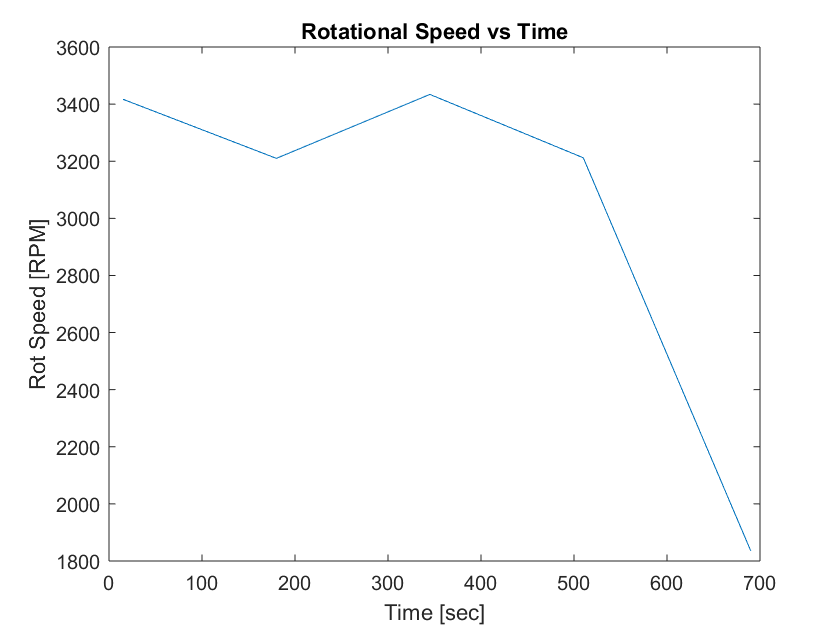


figure(3)
plot(time, rot_speed_rpm); title('Rotational Speed vs Time'); 
xlabel('Time [sec]'); ylabel('Rot Speed [RPM]')

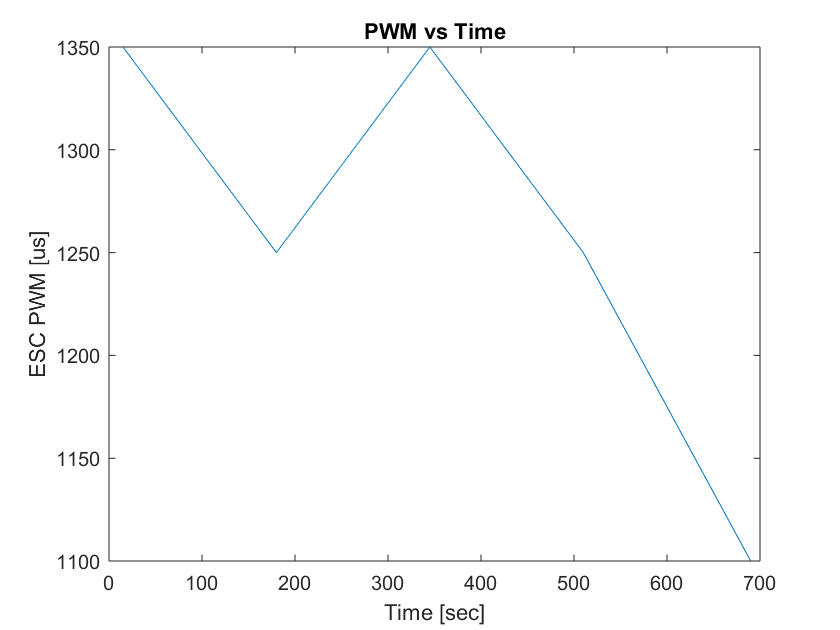


figure(4)
plot(time, PWM); title('PWM vs Time'); 
xlabel('Time [sec]'); ylabel('ESC PWM [us]')

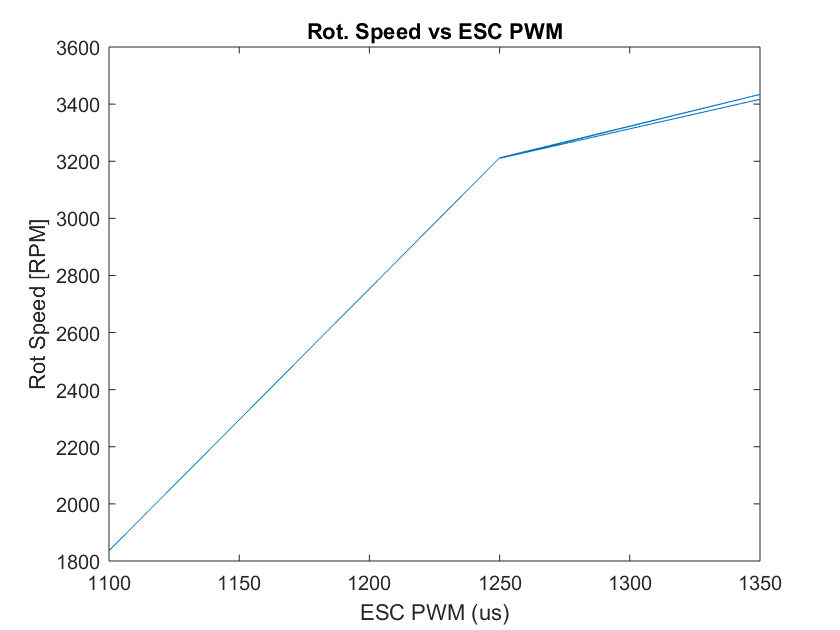


figure(5)
plot(PWM, rot_speed_rpm); title('Rot. Speed vs ESC PWM'); 
xlabel('ESC PWM (us)'); ylabel('Rot Speed [RPM]')